# Dereverberation

[signal, fs] = audioread('EchoSample.mp3');
% Take only the left channel from the stereo recording
signal = signal(:, 1);

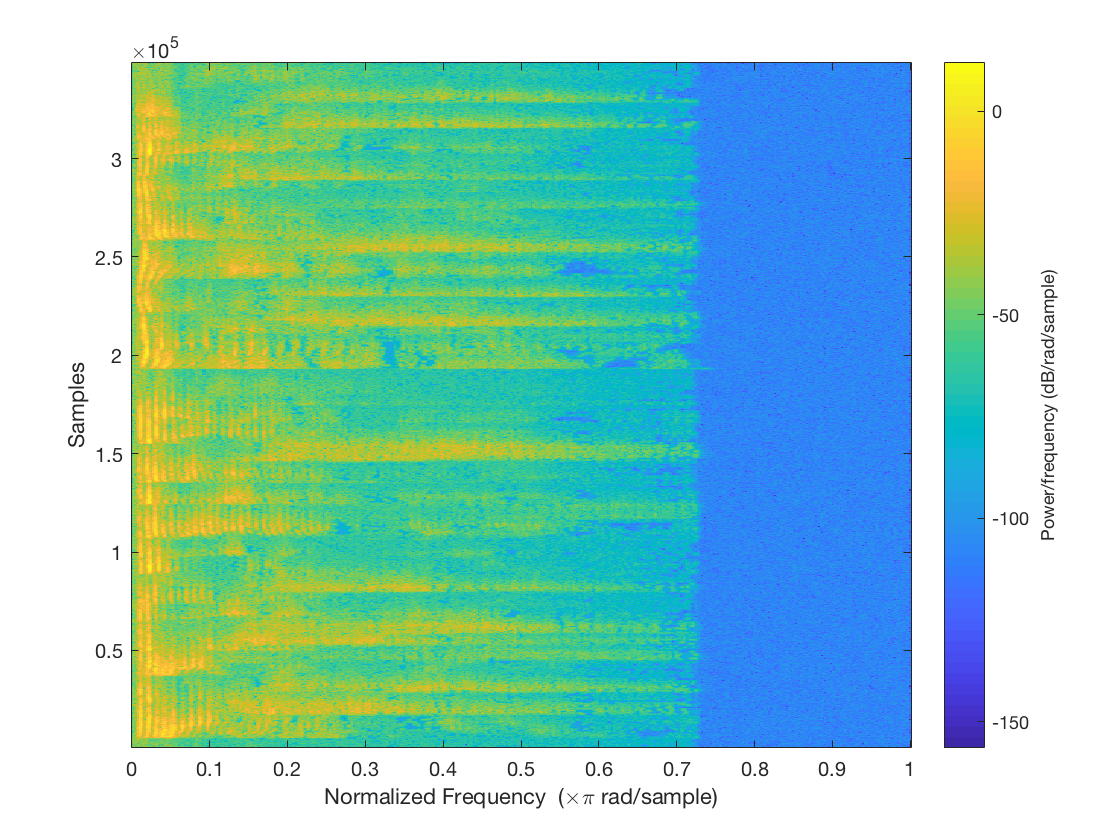

% Compute the signal's STFT with nfft=1024
% and a 50% overlapping Hann window.
stftWindowSize = 1024;
overlap = 0.75;
overlapSamples = overlap*stftWindowSize;
% TODO: zero padding?
window = hann(stftWindowSize);
[M,w,t] = spectrogram(signal, window, overlapSamples); %, fs)
spectrogram(signal, hann(stftWindowSize), overlap*stftWindowSize);

% M ('microphone') - input signal (reverberated) frequency-domain vectors.
% Rows - frequencies, Columns - time frames (middle time-point)

% Impulse response block length - has to be 'sufficiently small'
% TODO: experiment with value. Is this really the same as the window size?
D = stftWindowSize;
[frequencyCount, frameCount] = size(M);
B = 10; % Number of impulse response blocks - 1. TODO: experiment.

S = zeros(size(M)); % Dry signal frequency-domain vectors.
R = zeros(size(M)); % Reverberated components frequency-domain vectors.
% Minimum gain per frequency. TODO: Should be frequency specific? Experiment.
minGain = zeros(frequencyCount, 1);
bias = zeros(frequencyCount, B);
bias(:) = 1 + eps; % TODO: Experiment
maxHEstimate = zeros(frequencyCount, B);
% TODO: Experiment - should 'reflect real world systems' -
% e.g. exponential decay / given impulse response. (Page 11 - MaxValue.)
maxHEstimate(:) = 0.9;

H_pow = zeros(frequencyCount, B); % Reverberant system frequency response estimate blocks - power.
pow = @(x) abs(x).^2;

previousSFramesPower = zeros(frequencyCount, B); % Most recent previous frame is first.
previousMFramesPower = ones(frequencyCount, B); % Most recent previous frame is first.

C = zeros(size(H)); % Reverberant system frequency response power estimate blocks - temporary.
for inputFrameIndex = 1:frameCount
    inputFrame = M(:, inputFrameIndex);
    inputFramePower = pow(frame);
    
    % Update system frequency response estimates.
    for blockIndex=1:B
        newEstimates = inputFramePower ./ previousMFramesPower(:, blockIndex);
        unchanged = newEstimates >= H_pow(:, blockIndex);
        newEstimates(unchanged) = H_pow(unchanged, blockIndex) .* bias(unchanged, blockIndex) + eps;
        C(:, blockIndex) = min(newEstimates, maxHEstimate(:, blockIndex));
        % TODO: Temporal smoothing (Page 11).
        H_pow(:, blockIndex) = C(:, blockIndex);
    end
    
    G_S = 1 - (sum(previousSFramesPower .* H_pow)) ./ inputFramePower;
    % Enforce a minimum gain for each frequency.
    G_S = max([G_S minGain], [], 2);
    G_R = 1 - G_S;
    % TODO: Apply gain smooting over time to G_S and G_R.
    S(:, inputFrameIndex) = G_S .* inputFrame;
    R(:, inputFrameIndex) = G_R .* inputFrame;
    
    % Shift all previous frames one column to the right, and insert the
    % current frame at the beginning.
    previousSFramesPower(:, 2:end) = previousSFramesPower(:, 1:end-1);
    previousSFramesPower(:, 1) = pow(S(:, inputFrameIndex));
    
    previousMFramesPower(:, 2:end) = previousMFramesPower(:, 1:end-1);
    previousMFramesPower(:, 1) = inputFramePower;
end

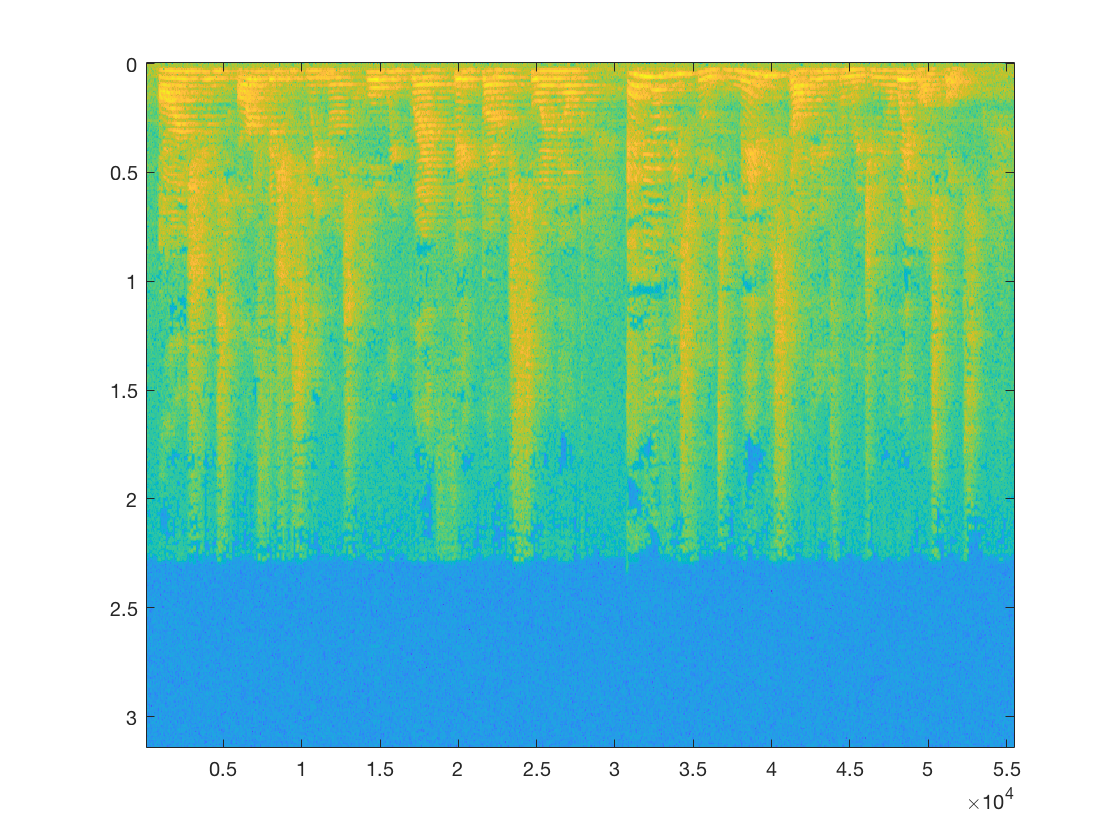

% Display the spectrum power before and after:
figure;
imagesc(t, w, 10*log10(abs(M)+eps));

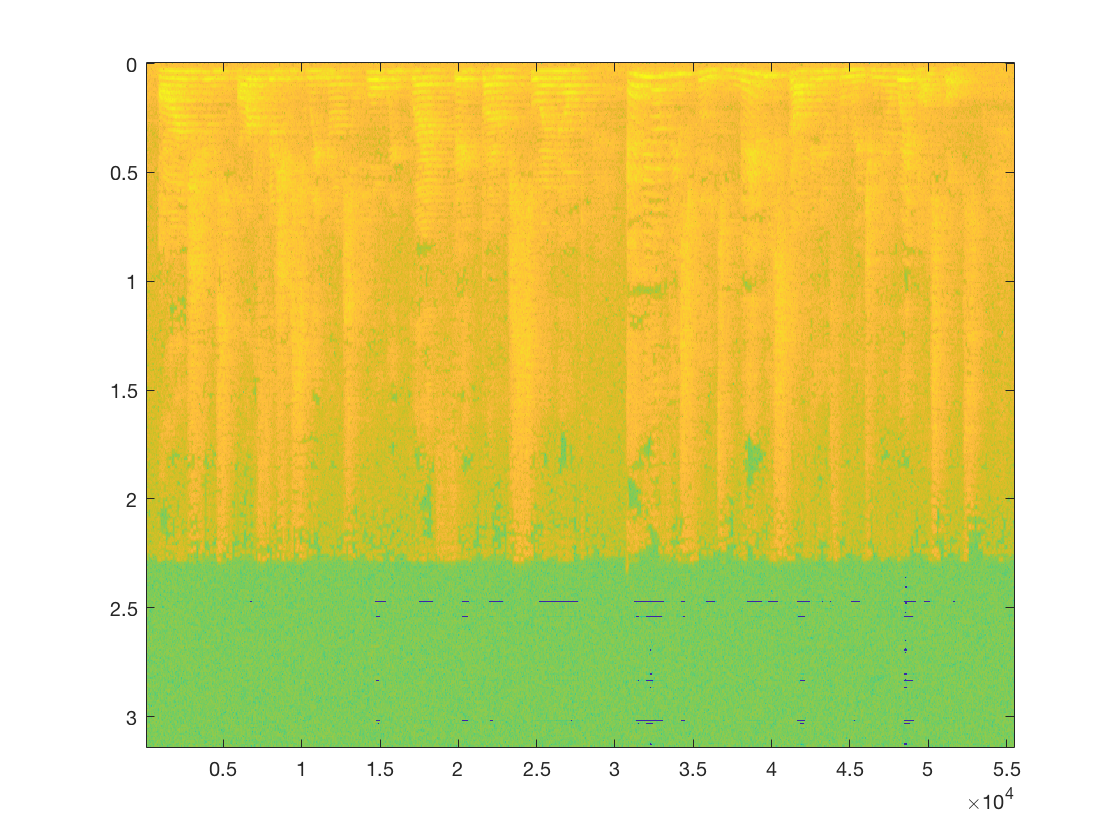

figure;
imagesc(t, w, 10*log10(abs(S)+eps));

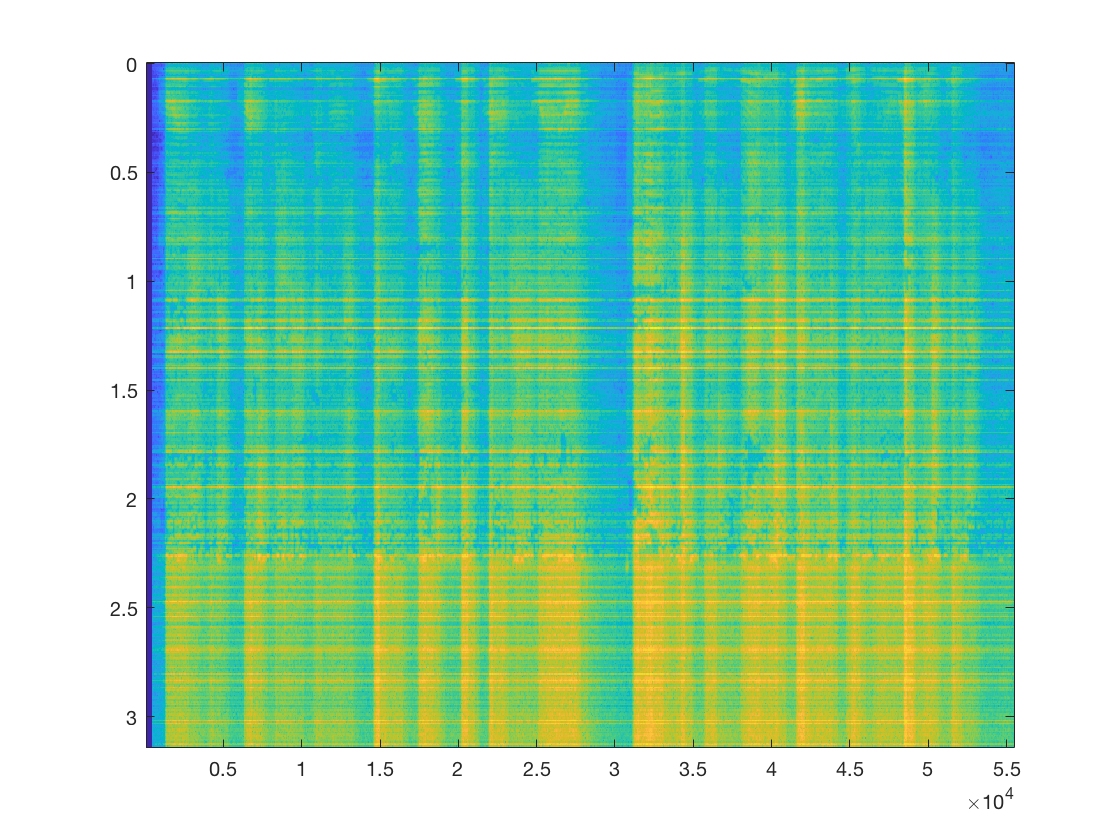

figure;
imagesc(t, w, 10*log10(abs(R)+eps));

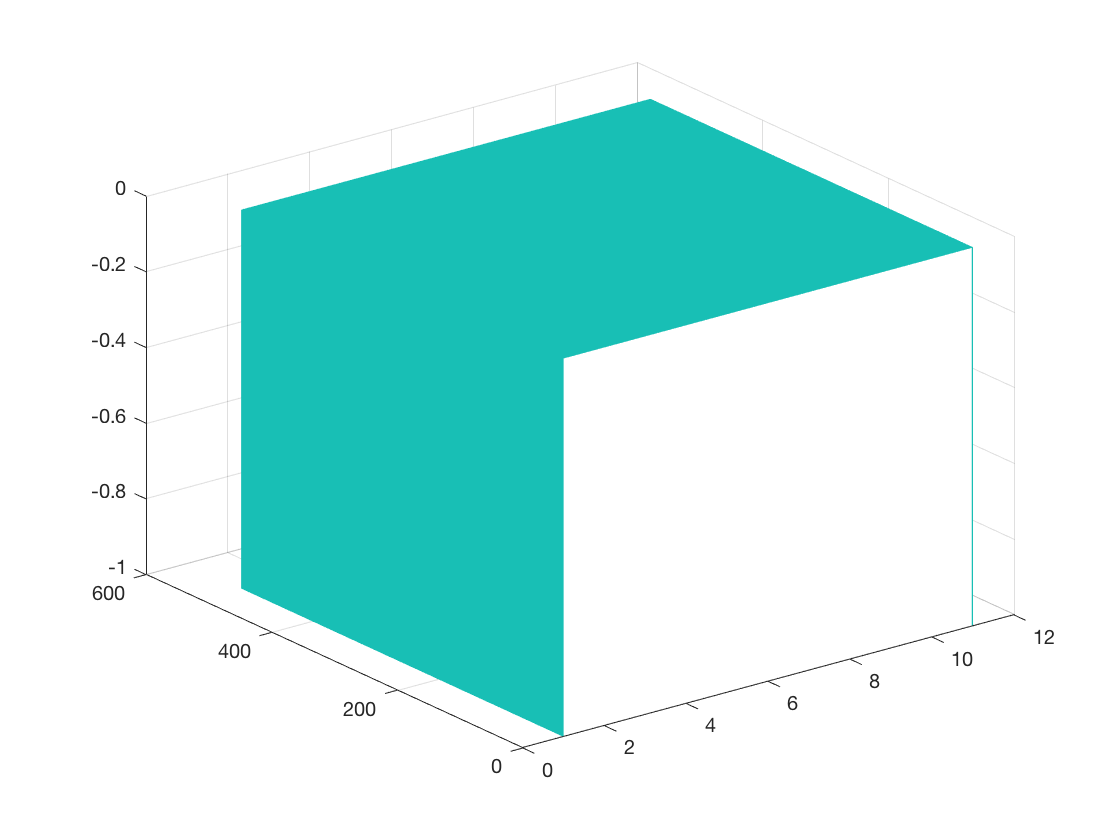



waterfall(H)

% Reconstruct the signal using the IFFT, applying the time-domain window to
% each reconstructed block and then adding them together ("overlap-add"
% technique).
% Make one-sided spectrum conjugate symmetric:
S(frequencyCount+1:stftWindowSize, :) = conj(flipud(S(1:frequencyCount-2, :)));
outputLength = length(signal);
output = zeros(outputLength, 1);
stftHop = stftWindowSize - overlapSamples;
for frameIndex = 1:frameCount
  frameStart = (frameIndex-1)*stftHop;
  if frameStart + stftWindowSize > outputLength
      break
  end
  sampleRange = frameStart+1 : frameStart+stftWindowSize;
  reconstructedFrame = window .* ifft(S(:, frameIndex), 'symmetric');
  output(sampleRange) = output(sampleRange) + reconstructedFrame;
end

spectrogram(signal, window, overlapSamples);

soundsc([signal; output], fs);